cAMPFreSimvsAnaSoluvsSimBio

无量纲化分析 考虑bPAC瞬间失活 

https://jinlab.yuque.com/vwt6oc/bu7rel/guwgitem33kes6wf

2.3.1 和2.3.2 理论解析解与数值积分比较 并与simBio进行对比 2023/7/12

Shuai Yang 

2023/7/5    2023/7/12

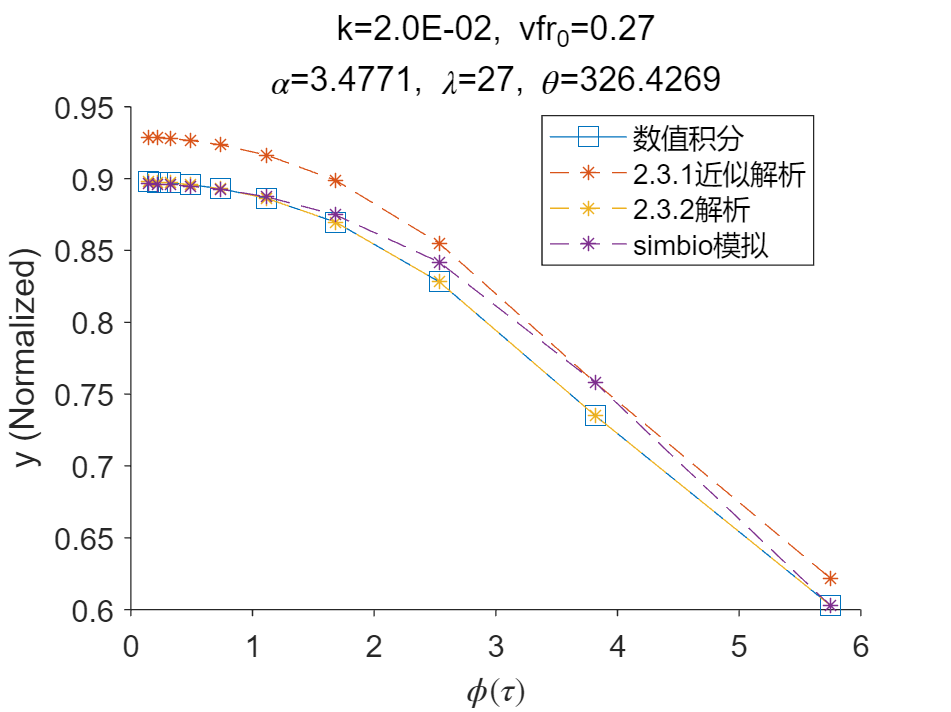


clear; clc;
% k= k0[bPAC*],光照后bPAC*为恒定值，k代表光照后bPAC*生产cAMP的率
k = 0.02;% 默认 0.0045 uM/s = k0 * bPAC
gamma = 0.002876;% s-1,cAMP被降解的速率
beta = 0.2; %s-1, bPAC失去活性的速率
% T = 1000;% 信号输入的周期 s
P = 0.2;% 占空比
dt = 0.1;% delt t 分割的时间间隔 0.1s
%%
% cAMP与调控蛋白Vfr结合形成Vfr_cAMP2的复合物。表观解离常数K1，希尔系数n1;
n1 = 2; %
K1 = 2; % uM
% Vfr_cAMP2复合物与启动子的结合表观解离常数为K2 ，希尔系数n2
n2 = 1; %
K2 = 0.01; % 0.01uM = 10nM
Vfr = 0.27;% uM TF因子数目 默认0.27
DNA = 0.005; % uM 启动子的DNA数目
lambda = Vfr/K2;
cAMPmax = k / gamma; % cAMP 最大表达量
promax = DNA*10/3E-4; % 所有 DNA 全部激活，蛋白最大表达量

Tset = logspace(log10(50),log10(2E3),10);
% xTickNames = string(Tset);
y_output1 = NaN(size(Tset));
y_output2 = NaN(size(Tset));
y_output3 = NaN(size(Tset));
y_output4 = NaN(size(Tset));
x_HL = NaN(2,numel(Tset));
s_HL = NaN(2,numel(Tset));
s_sim = NaN(2,numel(Tset));

for iPeroid = 1:numel(Tset)
    T = Tset(iPeroid); 

    x_High = (1-exp(-gamma*T*P))/(1-exp(-gamma*T));
    x_Low = x_High*exp(-gamma*(T-T*P));

    t = 0:dt:T;
    x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
        (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

    a = k/gamma;
    phi = gamma*T;
    tao = gamma*t;

    % sH = x_High/a;
    % sL = x_Low/a;

    sH = (1-exp(-phi*P))/(1-exp(-phi));
    sL = (exp(phi*P)-1)/(exp(phi)-1);

    dtao = dt*gamma;
    s_tao = (1-(1-sL)*exp(-tao)).*(tao<=phi*P)+...
        (sH*exp(-tao+phi*P)).*(tao>phi*P);

    % 验证
    % figure,plot(x);hold on,plot(s_tao*a,'--');% 两条曲线重合

    theta = lambda*(a/K1)^2;
    alpha = k/(gamma*K1);



    % 针对 lambda远远大于1 的近似情况 瞬间失活的 积分
    y = (1/phi)*((theta/(1+theta)*log((1-sL)*sqrt(1+theta*(sH)^2)/((1-sH)*sqrt(1+theta*(sL)^2))))- ...
        (sqrt(theta)/(1+theta)*atan(sqrt(theta)*(sH-sL)/(1+theta*sL*sH))));


    sH1 = sinh(phi*P/2)/sinh(phi/2)*exp(phi*(1-P)/2);
    sL1 = sinh(phi*P/2)/sinh(phi/2)*exp(-phi*(1-P)/2);

    testP = 1/phi*log((1-sL)/(1-sH));

    y_test = (1/phi)*((theta/(1+theta)*log(sqrt(1+theta*(sH)^2)/sqrt(1+theta*(sL)^2)))- ...
        (sqrt(theta)/(1+theta)*atan(sqrt(theta)*(sH-sL)/(1+theta*sL*sH))))+theta*P/(1+theta);


    % 不针对 lambda大于1 进行近似
    y1 = (1/phi)*((lambda*alpha^2/(1+(lambda+1)*alpha^2))*log(sqrt(1+(lambda+1)*alpha^2*sH^2)/sqrt(1+(lambda+1)*alpha^2*sL^2))-...
        alpha*lambda/sqrt(lambda+1)/(1+(lambda+1)*alpha^2)*atan(alpha*sqrt(lambda+1)*(sH-sL)/(1+(lambda+1)*alpha^2*sL*sH)))+...
        lambda*alpha^2*P/(1+(lambda+1)*alpha^2);

    x1 = x/K1;
    u = lambda./((1+lambda)+1./x1.^2);
    u1 = cAMPOutPut1(t,T,k,gamma,P,lambda,K1);

    fun =@(t,T) cAMPOutPut1(t,T,k,gamma,P,lambda,K1); % returns fun(t,T);
    q = integral(@(t) fun(t,T),0,T);
    q1 = q/T;

    y_output1(iPeroid) = q1;% 数值积分
    y_output2(iPeroid) = y; % bPAC 瞬间失活 针对λ远大于1的近似
    y_output3(iPeroid) = y1;% bPAC 瞬间失活 一般情况未近似

    x_HL(1,iPeroid) = x_High;
    x_HL(2,iPeroid) = x_Low;
    s_HL(1,iPeroid) = sH1;
    s_HL(2,iPeroid) = sL1;

    %%% 加入simbio模拟
    sbioloadproject FAC.sbproj;
    m1.Species(1).Value = k / m1.Parameters(2).Value;
    m1.Species(3).Value = Vfr;
    m1.Species(5).Value = DNA;
    m1.Parameters(1).Value = beta;
    m1.Parameters(4).Value = gamma;
    m1.Parameters(5).Value = K1^n1 * m1.Parameters(3).Value;
    m1.Parameters(7).Value = K2 * m1.Parameters(6).Value;
    [~,promean,tt,dd] = FACequimean(m1,T,P,m1.Species(1).Value,beta);
    x0 = find(tt>tt(end)-T*3,1,"first");

%     figure; subplot(2,2,1); plot(tt,dd(:,1)); title('bPAC');
%     subplot(2,2,2); plot(tt,dd(:,2)); title('cAMP');
%     subplot(2,2,3); 
%         yyaxis left;
%         plot(tt,dd(:,3)); hold on;
%         plot(tt,dd(:,4)); hold on;
%         yyaxis right;
%         plot(tt,dd(:,6)); hold on;
%         plot(tt,dd(:,5));
%         legend('vfr','vfr-cAMP-cAMP','TF-DNA','pDNA',Location='best');
%     subplot(2,2,4); plot(tt,dd(:,7)); title('protein');
    
    y_output4(iPeroid) = promean/promax;
    s_sim(1,iPeroid) = max(dd(x0:end,2))/cAMPmax;
    s_sim(2,iPeroid) = min(dd(x0:end,2))/cAMPmax;
end

f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset*gamma,y_output1,'Marker','square','MarkerSize',10,'DisplayName','数值积分')
hold on,plot(Tset*gamma,y_output2,'LineStyle','--','Marker','*','DisplayName','2.3.1近似解析')
hold on,plot(Tset*gamma,y_output3,'LineStyle','--','Marker','*','DisplayName','2.3.2解析')
hold on,plot(Tset*gamma,y_output4,'LineStyle','--','Marker','*','DisplayName','simbio模拟')

set(ax1,'Tickdir','out','Box','off','FontSize',12);
legend(ax1,'show',Location='best');
xlabel(ax1,'$\phi (\tau)$', Interpreter='latex');
ylabel(ax1,'y (Normalized)')
title(sprintf('k=%.1E, vfr_0=%.2f',k,Vfr), ...
    ['\alpha=',num2str(alpha),', \lambda=',num2str(lambda), ', \theta=',num2str(theta)]);

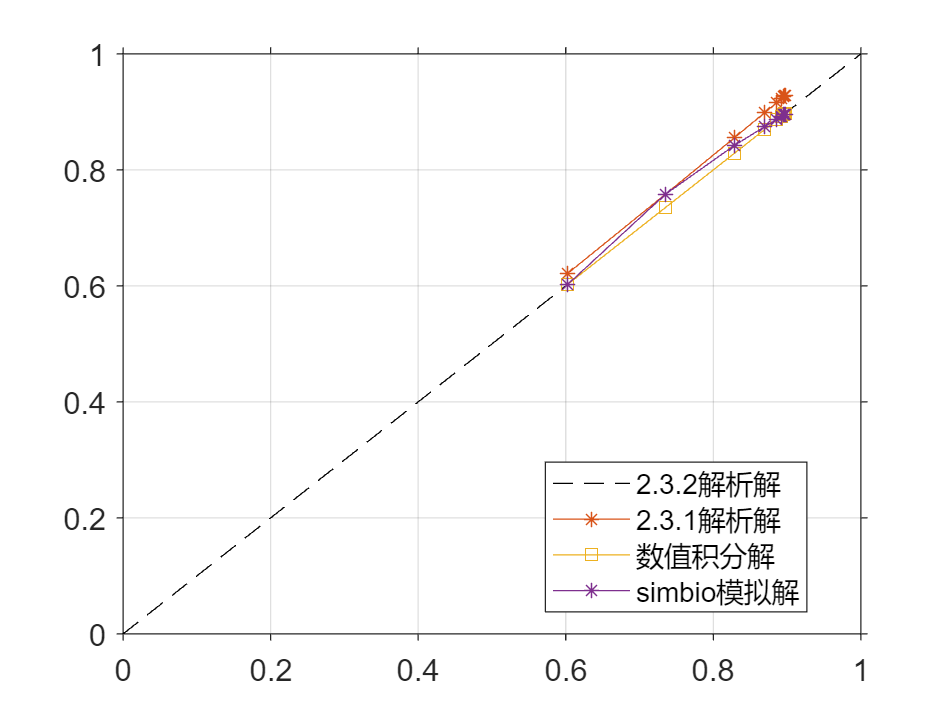


f2 = figure; ax2 = axes('Parent',f2);
plot(0:0.01:1,0:0.01:1,'k--','DisplayName','2.3.2解析解'); hold on;
plot(y_output3,y_output2,'Marker','*','DisplayName','2.3.1解析解'); hold on;
plot(y_output3,y_output1,'Marker','s','DisplayName','数值积分解'); hold on;
plot(y_output3,y_output4,'Marker','*','DisplayName','simbio模拟解'); hold on;
% xlim([0.35,0.6]); ylim([0.35,0.6]); xticks(0.35:0.05:0.6); xticks(0.35:0.05:0.6);
set(ax2,'Tickdir','out','Box','on','FontSize',12); grid; legend(ax2,'show',Location='best');

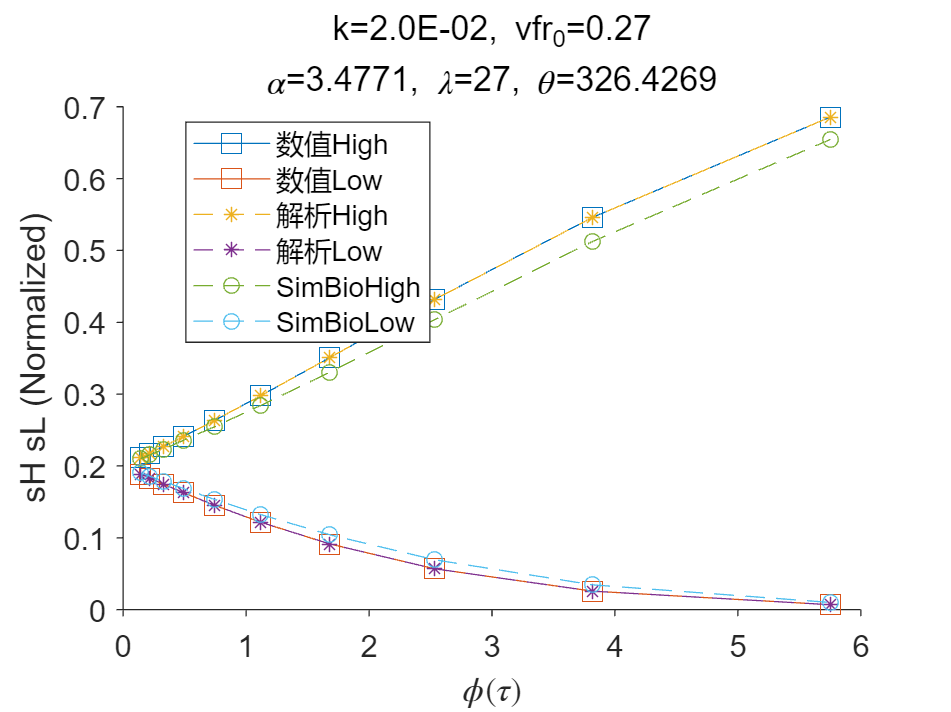

legend(ax1,'show')


f1 = figure;
ax1 = axes('Parent',f1);
plot(Tset*gamma,x_HL,'Marker','square','MarkerSize',10)
hold on,plot(Tset*gamma,s_HL,'LineStyle','--','Marker','*')
hold on; plot(Tset*gamma,s_sim,'LineStyle','--','Marker','o')
legend('数值High','数值Low','解析High','解析Low','SimBioHigh','SimBioLow',Location='best')
legend(ax1,'show')
set(ax1,'Tickdir','out','Box','off','FontSize',12);
xlabel(ax1,'$\phi (\tau)$',Interpreter='latex');
ylabel(ax1,'sH sL (Normalized)')
title(sprintf('k=%0.1E, vfr_0=%.2f',k,Vfr), ...
    ['\alpha=',num2str(alpha),', \lambda=',num2str(lambda), ', \theta=',num2str(theta)]);

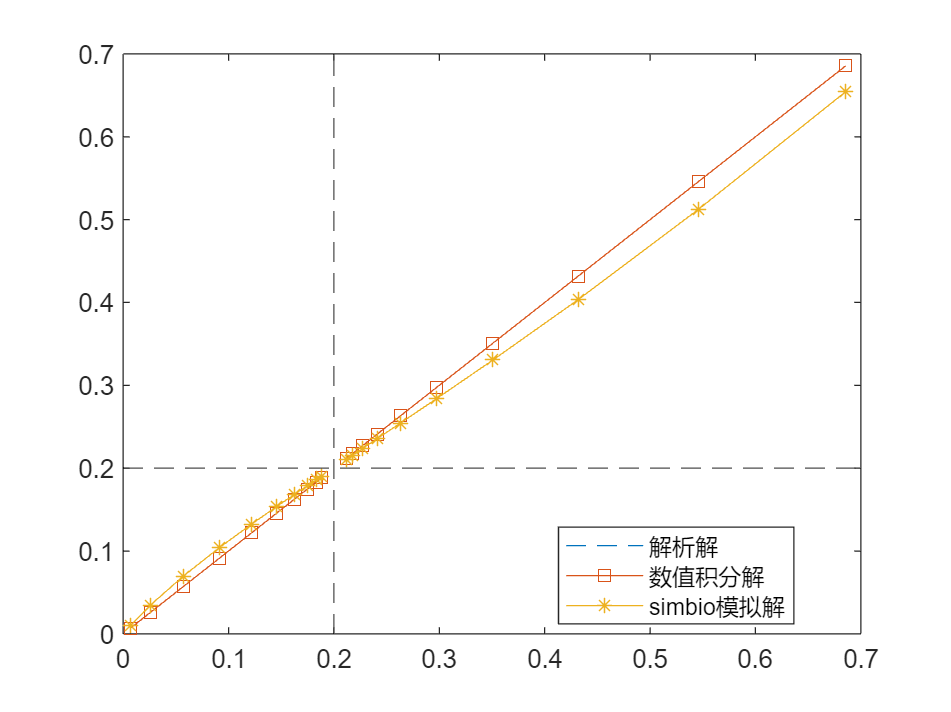


f2 = figure; ax1 = axes('Parent',f2); grid on; 
xlim([0,0.7]); ylim([0,0.7]); xticks(0:0.1:0.7);
p11 = plot(s_HL(1,:),s_HL(1,:),'--'); hold on; 
p21 = plot(s_HL(1,:),x_HL(1,:),'s-'); hold on;
p31 = plot(s_HL(1,:),s_sim(1,:),'*-'); hold on;
p12 = plot(s_HL(2,:),s_HL(2,:),'--'); p12.Color = p11.Color; hold on;
p22 = plot(s_HL(2,:),x_HL(2,:),'s-'); p22.Color = p21.Color; hold on;
p32 = plot(s_HL(2,:),s_sim(2,:),'*-'); p32.Color = p31.Color; hold on;
xline(0.2,'k--'); hold on; yline(0.2,'k--'); hold on;
legend('解析解','数值积分解','simbio模拟解',Location='best');

function u = cAMPOutPut1(t,T,k,gamma,P,lambda,K1)
% bPAC 瞬间失活的情况 beta的事情
% 光照结束既是cAMP浓度最高时

x_High = (k/gamma)*(1-exp(-gamma*T*P))/(1-exp(-gamma*T));
x_Low = x_High*exp(-gamma*(T-T*P));

x = ((x_Low-k/gamma)*exp(-gamma*t)+k/gamma).*(t<=T*P)+...
    (x_High*exp(-gamma*(t-T*P))).*(t>T*P);

x1 = x/K1;
u = lambda./((1+lambda)+1./x1.^2);
end

function [m1,promean,tt,dd] = FACequimean(m1,T,P,bPAC0,beta)
% this function used to measure FAC model equi-state mean protein;
    totaltime = 5E4; num = 20;
    tt = zeros(ceil(totaltime/T)*2*num,1);
    dd = zeros(ceil(totaltime/T)*2*num,numel(m1.Species));
    for ii = 1:ceil(totaltime/T)
        % 一个周期内；
        % 光照分为 num 份拟合；
        for i = 1:num
            m1.configset.StopTime = T*P/num;
            m1.Species(1).Value = bPAC0;
            m1.Parameters(1).Value = 0;
            [~,sd1,nms] = sbiosimulate(m1);
            tt(i+(ii-1)*2*num) = (ii-1)*T + i*T*P/num;
            dd(i+(ii-1)*2*num,:) = sd1(end,:);
            for j = 1:numel(nms)
                m1.Species(j).Value = sd1(end,j);
            end
        end
        % 黑暗分为 num 份拟合；
        for i = 1:num
            m1.configset.StopTime = T*(1-P)/num;
            m1.Species(1).Value = 0;
            m1.Parameters(1).Value = beta;
            [~,sd0,nms] = sbiosimulate(m1);
            tt(i+num+(ii-1)*2*num) = (ii-1)*T+T*P + ...
                i*T*(1-P)/num;
            dd(i+num+(ii-1)*2*num,:) = sd0(end,:);
            for j = 1:numel(nms)
                if sd0(end,j) < 1E-10
                    m1.Species(j).Value = 0;
                else
                    m1.Species(j).Value = sd0(end,j);
                end
            end
        end
        % 记录最后一个周期的数值计算均值；
        if ii == ceil(totaltime/T)
            promean = ( mean(sd1(:,7))*(T*P)+mean(sd0(:,7))*(T*(1-P)) )/T;
        end
    end
end
